#                                                             Read an image, apply erosion and subtract result from og

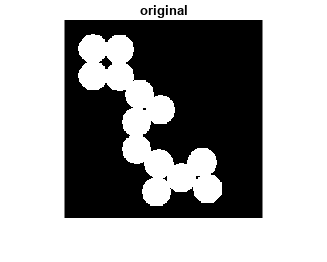

imgBW = imread('circles.png');
imshow(imgBW);
title("original");

Apply erosion

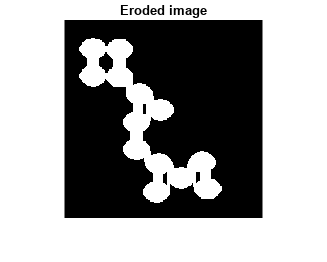

se = strel('line',11,90);
er_img =  imerode(imgBW, se);
imshow(er_img);
title("Eroded image");

Dilation

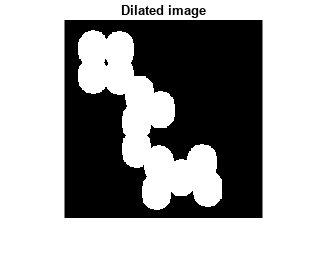

de_img = imdilate(imgBW, se);
imshow(de_img);
title("Dilated image");

Subtracting result from og

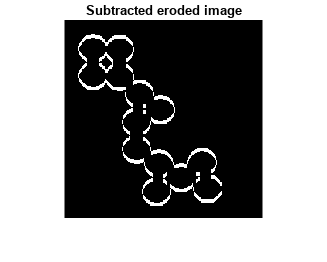

n_img = imsubtract(imgBW, er_img);
imshow(n_img);
title("Subtracted eroded image");

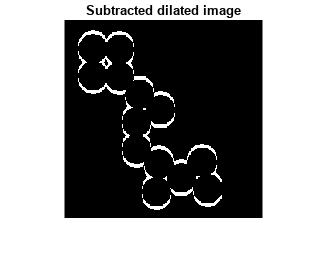

d_img = imsubtract(de_img, imgBW);
imshow(d_img);
title("Subtracted dilated image");